% Andrew Hutsell
% MATH 515
% Problem Set 1



clear; clc; close all;
% Problem 1


function [pi, n] = PS1(tolerance)
    % My value of starting out at 0
    pi = 0;
    % True value of pi to compare to the computed solution
    true_pi = 3.1415926;
    % Count the number of terms used
    n = 0;

    while abs(pi - true_pi) > tolerance
        term = 4 * (((-1)^n)/ (2 * n + 1));
        pi = pi + term;
        n = n + 1;
    end
end

tolerance_b = 5e-3;
[pi_b, n_b] = PS1(tolerance_b);
fprintf('pi ≈ %.10f\n', pi_b)

pi ≈ 3.1365926848


fprintf('Number of terms used: %d\n', n_b)

Number of terms used: 200



tolerances_c = [5e-3, 1e-3, 5e-4, 1e-4, 1e-5];
pi_values = [];
n_values = [];
for i = 1:length(tolerances_c)
    [pi_i, n_i] = PS1(tolerances_c(i));
    pi_values(i) = pi_i;
    n_values(i) = n_i;

end


figure;
loglog(tolerances_c, n_values)
grid on; 
xlabel('Tolerances'); 
ylabel('Number of Required Terms'); 
title('Tolerances vs Number of Terms');

p = polyfit(log(tolerances_c), log(n_values), 1);
slope = p(1)

slope = -0.9992

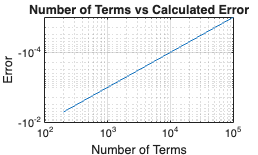


% Error Calculation
true_pi = 3.1415926;
errors = [];
for i = 1:length(tolerances_c)
    errors(i) = pi_values(i) - true_pi;
end

figure;
loglog(n_values, errors)
grid on; 
xlabel('Number of Terms'); 
ylabel('Error'); 
title('Number of Terms vs Calculated Error');

% Problem 2


% Problem 3


% Problem 4
a = 1;
b = 4;
c = 8;

disc = sqrt(b^2 - (4 * a * c))

disc = 0.0000 + 4.0000i

root1 = -2*c / (b + disc)

root1 = -2.0000 + 2.0000i

root2 = -(b/a) - root1

root2 = -2.0000 - 2.0000i

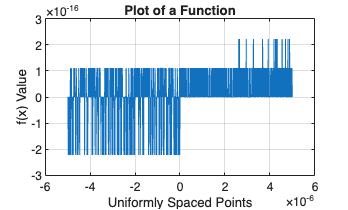

clear; clc; close all;
% Problem 5
% Part a
x = linspace(-5e-6, 5e-6, 1001);
f = log(1+x) - cos(x) - x + 1;

plot(x,f)
grid on; 
xlabel('Uniformly Spaced Points'); 
ylabel('f(x) Value'); 
title('Plot of a Function');

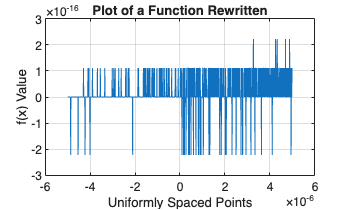


% Part b
f_rewrite = log(1+x) - x - cos(x) + 1;
plot(x,f_rewrite)
grid on; 
xlabel('Uniformly Spaced Points'); 
ylabel('f(x) Value'); 
title('Plot of a Function Rewritten');

Part c

for a) log(1+x) and x are equal at numerous points (hence the noise from -5e-6 to 0)

for b) the cancellation errors are dramatically reduced because the smaller quantities are grouped together and the lerge terms are not directly subtracted with one another.

% Problem 6


% Problem 7
A = [3.4 2.8; 8.0 6.6];
b = [3.41; 8.0];

x = A\b

x =     2.6500
   -2.0000



det = det(A)

det = 0.0400